Data = readtable("../design and analysis/tensileStrengthData.csv")

Data = 81×2 table
     Var1      Var2 
    ______    ______

    1540.2     -0.38
    1540.2      0.02
    1637.1      0.24
    1540.2      0.39
    1541.9      0.16
    1540.2     -0.05
    1541.9     -0.75
    1550.4     17.04
    1540.2     50.81
    1541.9    170.35
    1541.9     205.9
    1507.9    502.93
    1540.2    826.31
    1637.1      1259
    1637.1      1647
    1637.1    1810.4


Data2 = readtable("../design and analysis/tensileStrengthData2.csv")

Data2 = 123×2 table
     Var1      Var2 
    ______    ______

         1     -0.09
    1584.4     -0.37
    1572.5      0.07
    1582.7     -0.05
    1572.5     -0.21
    1572.5       0.2
    1572.5      0.09
    1572.5      0.06
    1572.5     -0.09
    1572.5     -0.11
    1574.2     -3.47
    1574.2     -7.83
    1572.5    -31.41
    1572.5    -25.14
    1572.5    115.58
    1552.1    329.38



Area = (.02)*(0.000762)

Area = 1.5240e-05


Weight = table2array(Data(:,2));
Weight2 = table2array(Data2(:,2));

Distance = table2array(Data(:,1));
Distance2 = table2array(Data2(:,1));

Force = Weight.*0.0098;
Force2 = Weight2.*0.0098;

for i=1:length(Force)
        if (0 > Force(i)) && (Force(i) > -115)
            Force(i) = 0;
        elseif (Force(i) < -115)
            Force(i) = Force(i-1) + 0.3; 
        end
    
end 
for i=1:length(Force2)
        if (0 > Force2(i)) && (Force2(i) > -75)
            Force2(i) = 0;
        elseif (Force2(i) < -75)
            Force2(i) = Force2(i-1) + 0.3; 
        end
    
end 

 for i=1:length(Distance)
   if (i>1) && (Distance(i) < Distance(i-1))
       Distance(i) = Distance(i-1) + 0.01;
    end
end
for i=1:length(Distance2)
    if (i>1) && (Distance2(i) < Distance2(i-1))
        Distance2(i) = Distance2(i-1) + 0.01;
    end
end



Stress = Force / Area

Stress = 	1.0e+06 *

         0
    0.0000
    0.0002
    0.0003
    0.0001
         0
         0
    0.0110
    0.0327
    0.1095


Stress2 = Force2 / Area

Stress2 = 	1.0e+06 *

         0
         0
    0.0000
         0
         0
    0.0001
    0.0001
    0.0000
         0
         0


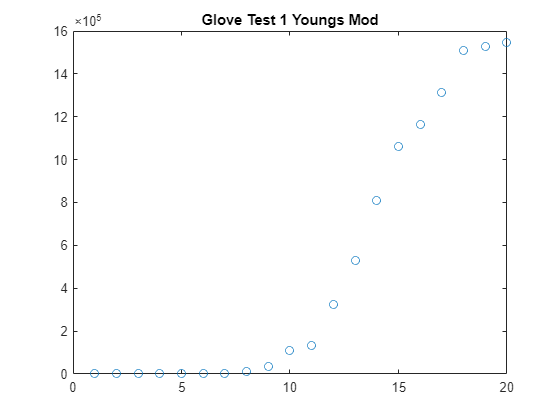


plot(Stress(1:20),'o')
title('Glove Test 1 Youngs Mod')

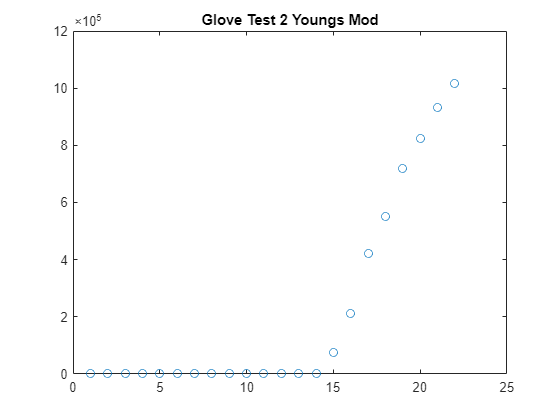

plot(Stress2(1:22),'o')
title('Glove Test 2 Youngs Mod')


Youngsmod1 = (1059110 - 32673.1)/(15-9)

Youngsmod1 = 1.7107e+05

Youngsmod2 = (1017000-74323.1)/(22-15)

Youngsmod2 = 1.3467e+05


Ulttens1=max(Stress)

Ulttens1 = 2.2930e+06

Ulttens2=max(Stress2)

Ulttens2 = 1.8185e+06

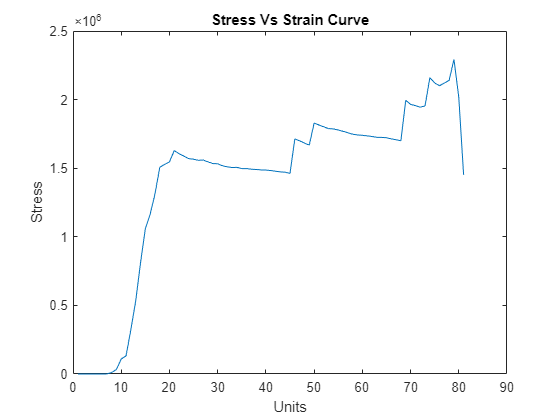


plot(Stress)
ylabel("Stress")
xlabel("Units")
title("Stress Vs Strain Curve")

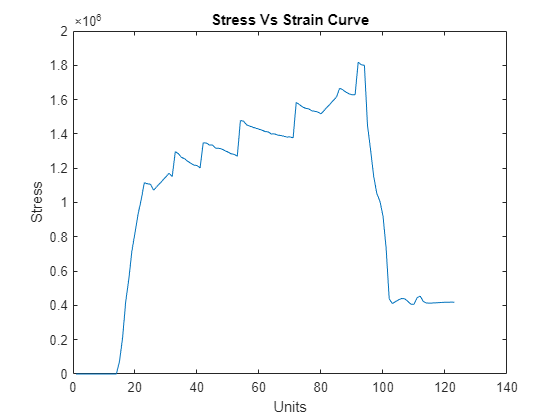

plot(Stress2)
ylabel("Stress")
xlabel("Units")
title("Stress Vs Strain Curve")

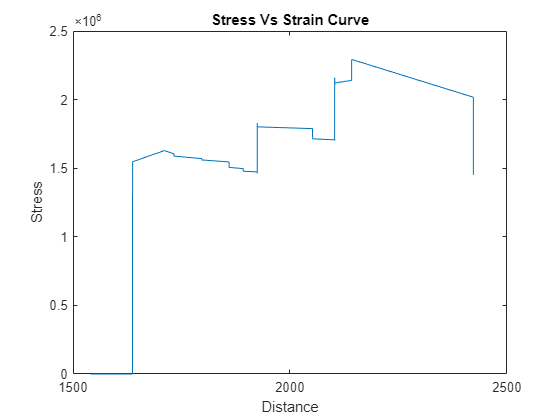



plot(Distance, Stress)
ylabel("Stress")
xlabel("Distance")
title("Stress Vs Strain Curve")

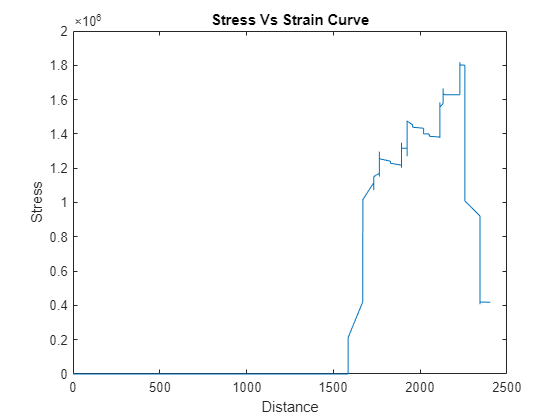

plot(Distance2, Stress2)
ylabel("Stress")
xlabel("Distance")
title("Stress Vs Strain Curve")